**Preliminaries**

clc 
ct.A=[-3.7 -7.5; 0 1];ct.B=[0;1];%System matrices
ct.nx=length(ct.A);ct.nu=size(ct.B,2);
if rank(ctrb(ct.A,ct.B))==length(ct.A)%Check controllability
    disp('CT System Controllable')
end

CT System Controllable


**Question 1**

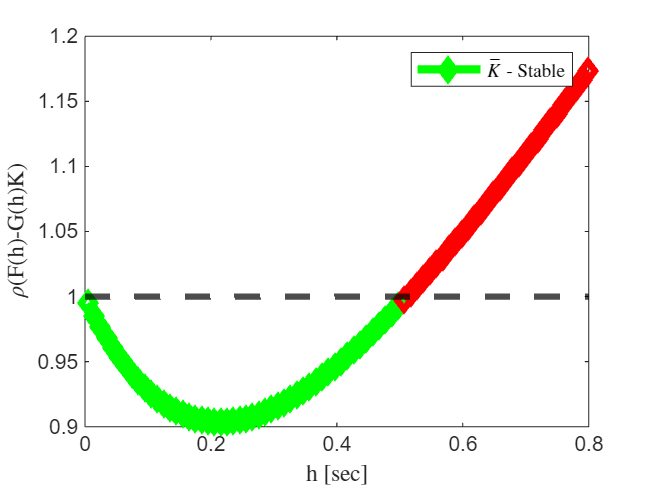

ct.clpoles=[-1+2i,-1-2i];%Desired closed loop poles
ct.K=place(ct.A,ct.B,ct.clpoles);%Static Feedback Gain

exp1.hmin=0.005;exp1.hmax=0.8;
exp1.hrange = linspace(exp1.hmin, exp1.hmax,80);%range of inter-sampling times
exp1.specrad = zeros(1, length(exp1.hrange));%vector of spectral radius vals
exp1.colors = zeros(length(exp1.hrange), 3); %Initialize color matrix
exp1.dummy=0;exp1.hbound=0;exp1.idbound=0;
for i = 1:length(exp1.hrange)
    [F, G] = ctsstodtss(ct.A, ct.B, exp1.hrange(i)); % DT matrices
    cloopmat = F - G * ct.K;%DT closed loop matrix
    exp1.specrad(i) = max(abs(eig(cloopmat)));
    if exp1.specrad(i) < 1
        exp1.colors(i, :) = [0 1 0]; % Green color
    else
        exp1.colors(i, :) = [1 1 1]; % Red color
        if exp1.dummy==0
            exp1.dummy=1;
            exp1.hbound=exp1.hrange(i-1);
            exp1.idbound=i-1;
        end
    end
end

figure
exp1.p=plot(exp1.hrange(1:exp1.idbound),exp1.specrad(1:exp1.idbound));
exp1.p.LineStyle='-';exp1.p.Marker='diamond';
exp1.p.Color=[0 1 0];exp1.p.LineWidth=4;
hold on
exp1.p2=plot(exp1.hrange(exp1.idbound:end),exp1.specrad(exp1.idbound:end));
exp1.p2.LineStyle='-';exp1.p2.Marker='diamond';
exp1.p2.Color=[1 0 0];exp1.p2.LineWidth=4;
yline(1,'LineWidth',3,'Color','k','LineStyle','--');
xlabel({'h [sec]'},'Interpreter','latex');
ylabel({'$\rho$(F(h)-G(h)K)'},'Interpreter','latex');
legend({'$\bar{K}$ - Stable',},'Interpreter','latex')

**Question 2.1: H versus Tau**

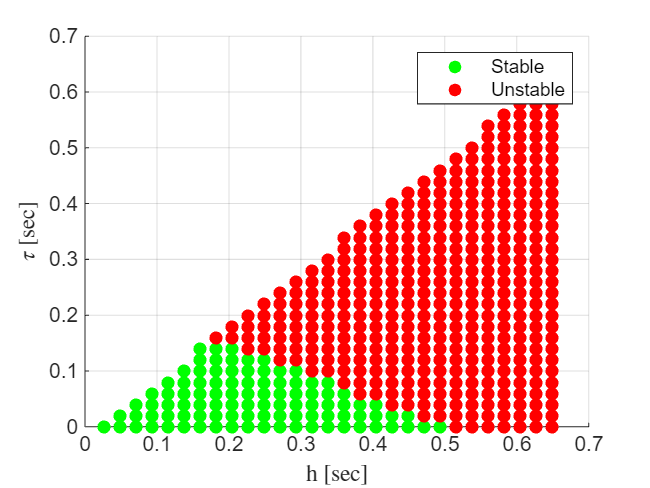

exp2.hmin=0.005;exp2.hmax=0.65;
exp2.hrange=linspace(exp2.hmin, exp2.hmax,30);%range of inter-sampling times
colors=[];scatterData=[];  

for i = 1:length(exp2.hrange)
    taumax=exp2.hrange(i)-0.02;
    for tau=0:0.02:taumax
        [F, G]=ctsstodtssdel(ct.A,ct.B,exp2.hrange(i),tau);
        cloopmat = F-G*[ct.K zeros(1, ct.nu)];% DT closed-loop matrix
        specrad=max(abs(eig(cloopmat)));
        if specrad<1
            colors = [colors; [0 1 0]];  % Green
        else
            colors = [colors; [1 0 0]];  % Red
        end
        scatterData = [scatterData; exp2.hrange(i) tau];
    end
end

figure
% Create a scatter plot
scatterHandle = scatter(scatterData(:, 1), scatterData(:, 2), 40, colors, 'filled');
xlabel({'h [sec]'},'Interpreter','latex')
ylabel({'$\tau$ [sec]'},'Interpreter','latex')
xlim=[0,0.65];
ylim=[0,0.45];
% Add legend
hold on;  % Keep the current plot
% Plot dummy points for legend
grid on
exp2.hstab = scatter([], [], 'green', 'filled', 'DisplayName', 'Stable');
exp2.hustab = scatter([], [], 'red', 'filled', 'DisplayName', 'Unstable');
legend([exp2.hstab exp2.hustab], 'Stable', 'Unstable');
hold off;  % Release the plot

**Question 2.2: LQR Approach**

q2D.h=0.4;q2D.tau=0.1;
[q2D.F,q2D.G]=ctsstodtssdel(ct.A,ct.B,q2D.h,q2D.tau);
[P,q2D.K,~]=idare(q2D.F,q2D.G,eye(ct.nu));

exp3.hmin=0.005;exp3.hmax=0.65;
exp3.hrange=linspace(exp3.hmin, exp3.hmax,500);%range of inter-sampling times
colors=[];scatterData=[];  

for i = 1:length(exp3.hrange)
    taumax=exp3.hrange(i)-0.01;
    for tau=0:0.01:taumax
        [F, G]=ctsstodtssdel(ct.A,ct.B,exp3.hrange(i),tau);
        cloopmat = F-G*q2D.K;%closed loop LQR Gain
        specrad=max(abs(eig(cloopmat)));
        if specrad<1
            colors = [colors; [0 1 0]];  % Green
        else
            colors = [colors; [1 0 0]];  % Red
        end
        scatterData = [scatterData; exp2.hrange(i) tau];
    end
end

Index exceeds the number of array elements. Index must not exceed 30.


% Create a scatter plot
scatterHandle = scatter(scatterData(:, 1), scatterData(:, 2), 40, colors, 'filled');
xlabel({'h [sec]'},'Interpreter','latex')
ylabel({'$\tau$ [sec]'},'Interpreter','latex')
xlim=[0,0.65];
ylim=[0,0.45];
% Add legend
hold on;  % Keep the current plot
% Plot dummy points for legend
exp2.hstab = scatter([], [], 'green', 'filled', 'DisplayName', 'Stable');
exp2.hustab = scatter([], [], 'red', 'filled', 'DisplayName', 'Unstable');
legend([exp2.hstab exp2.hustab], 'Stable', 'Unstable');
hold off;  % Release the plot

**Q2.2: Effect of K_u**

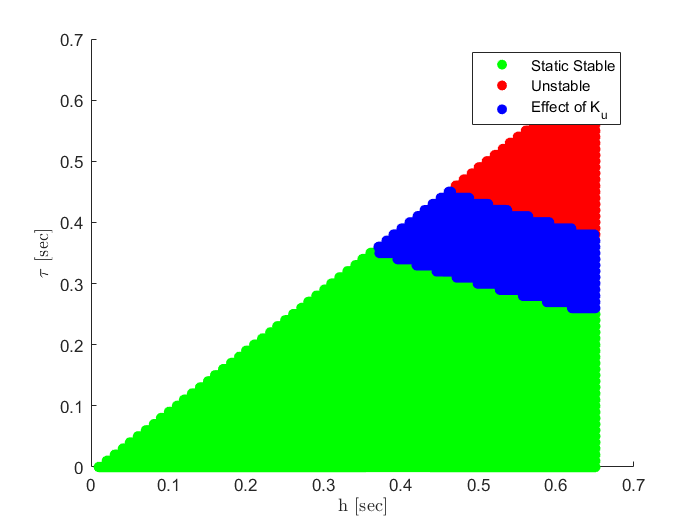

q2D.h=0.4; q2D.tau=0.1;
[q2D.F, q2D.G] = ctsstodtssdel(ct.A, ct.B, q2D.h, q2D.tau);
[P, q2D.K, ~] = idare(q2D.F, q2D.G, eye(ct.nu));

exp3.hmin = 0.005; exp3.hmax = 0.65;
exp3.hrange = linspace(exp3.hmin, exp3.hmax, 500); % range of inter-sampling times
colors = [];
scatterData = [];
orangeData = [];

for i = 1:length(exp3.hrange)
    taumax = exp3.hrange(i) - 0.01;
    for tau = 0:0.01:taumax
        [F, G] = ctsstodtssdel(ct.A, ct.B, exp3.hrange(i), tau);

        % Evaluate with the original control gain
        cloopmatOriginal = F - G * q2D.K; 
        specradOriginal = max(abs(eig(cloopmatOriginal)));

        % Evaluate with modified control gain
        modifiedK = q2D.K;
        modifiedK(3) = 0;
        cloopmatModified = F - G * modifiedK;
        specradModified = max(abs(eig(cloopmatModified)));

        if specradModified < 1
            colors = [colors; [0 1 0]];  % Green for static stable
        else
            colors = [colors; [1 0 0]];  % Red for unstable
        end
        scatterData = [scatterData; exp2.hrange(i) tau];

        % Add orange points only if stable with original and not stable with modified
        if specradOriginal < 1 && specradModified >= 1
            orangeData = [orangeData; exp2.hrange(i) tau]; % Collect data for stable points with the original gain
        end
    end
end

% Create scatter plot
scatterHandle = scatter(scatterData(:, 1), scatterData(:, 2), 40, colors, 'filled');
hold on;  % Keep the current plot

% Create scatter plot for original controller in orange
if ~isempty(orangeData)
    scatter(orangeData(:, 1), orangeData(:, 2), 40, [0 0 1], 'filled');
end

xlabel({'h [sec]'}, 'Interpreter', 'latex');
ylabel({'$\tau$ [sec]'}, 'Interpreter', 'latex');

% Add legend
staticStable = scatter([], [], 'green', 'filled', 'DisplayName', 'Static Stable');
unstable = scatter([], [], 'red', 'filled', 'DisplayName', 'Unstable');
additionalStable = scatter([], [],'blue', 'filled', 'DisplayName', 'Effect of K_u');
legend([staticStable, unstable, additionalStable]);
hold off;  % Release the plot

**Static LQR Controller**

q3Dzoh.h=0.4;
[q3Dzoh.F,q3Dzoh.G] = ctsstodtss(ct.A,ct.B,q3Dzoh.h);
[P,q3Dzoh.K,~]=idare(q3Dzoh.F,q3Dzoh.G,eye(ct.nu));
exp5.hmin=0.005;exp5.hmax=1.4;
exp5.hrange=linspace(exp5.hmin,exp5.hmax,80);%range of inter-sampling times
exp5.specrad = zeros(1, length(exp5.hrange));%vector of spectral radius vals
exp5.colors=zeros(length(exp5.hrange),3); %Initialize color matrix
exp5.dummy=0;exp5.idbound=0;
for i = 1:length(exp5.hrange)
    [F,G]=ctsstodtss(ct.A,ct.B,exp5.hrange(i));% DT matrices
    cloopmat = F-G*q3Dzoh.K;%DT closed loop matrix
    exp5.specrad(i) = max(abs(eig(cloopmat)));
    if exp5.specrad(i) < 1
        exp5.colors(i, :) = [0 1 0]; % Green color
    else
        exp5.colors(i, :) = [1 0 0]; % Red color
        if exp5.dummy==0
            exp5.dummy=1;
            exp5.idbound=i-1;
        end
    end
end

**Question 3.2**

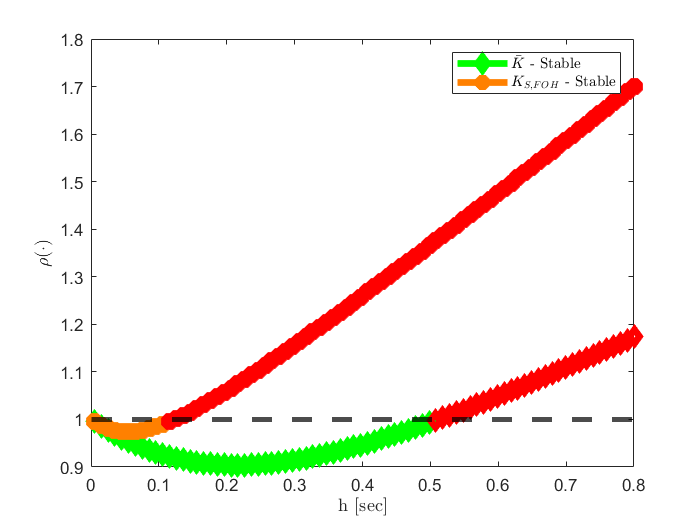

q32.K=[ct.K 0 0];
exp4.hmin=0.005;exp4.hmax=0.8;
exp4.hrange=linspace(exp4.hmin,exp4.hmax,80);%range of inter-sampling times
exp4.specrad = zeros(1, length(exp4.hrange));%vector of spectral radius vals
exp4.colors=zeros(length(exp4.hrange),3); %Initialize color matrix
exp4.dummy=0;exp4.idbound=0;
for i = 1:length(exp4.hrange)
    [F, G]=cttodt_smartac(ct.A,ct.B,exp4.hrange(i));% DT matrices
    cloopmat = F-G*q32.K;%DT closed loop matrix
    exp4.specrad(i) = max(abs(eig(cloopmat)));
    if exp4.specrad(i) < 1
        exp4.colors(i, :) = [0 1 0]; % Green color
    else
        exp4.colors(i, :) = [1 0 0]; % Red color
        if exp4.dummy==0
            exp4.dummy=1;
            exp4.idbound=i-1;
        end
    end
end

figure
exp1.p=plot(exp1.hrange(1:exp1.idbound),exp1.specrad(1:exp1.idbound));
exp1.p.LineStyle='-';exp1.p.Marker='diamond';
exp1.p.Color=[0 1 0];exp1.p.LineWidth=4;
hold on
exp1.p2=plot(exp1.hrange(exp1.idbound:end),exp1.specrad(exp1.idbound:end));
exp1.p2.LineStyle='-';exp1.p2.Marker='diamond';
exp1.p2.Color=[1 0 0];exp1.p2.LineWidth=4;

exp4.p=plot(exp4.hrange(1:exp4.idbound),exp4.specrad(1:exp4.idbound));
exp4.p.LineStyle='-';exp4.p.Marker='*';exp4.p.MarkerSize=10;
exp4.p.Color=[1 0.5 0];exp4.p.LineWidth=4;
exp4.p2=plot(exp4.hrange(exp4.idbound:end),exp4.specrad(exp4.idbound:end));
exp4.p2.LineStyle='-';exp4.p2.Marker='*';exp4.p2.MarkerSize=10;
exp4.p2.Color=[1 0 0];exp4.p2.LineWidth=4;
yline(1,'LineWidth',3,'Color','k','LineStyle','--');
xlabel({'h [sec]'},'Interpreter','latex');
ylabel({'$\rho(\cdot)$'},'Interpreter','latex');
legend({'$\bar{K}$ - Stable','','$K_{S,FOH}$ - Stable',''},'Interpreter','latex')

**Question 3.2: Dynamic LQR Controller**

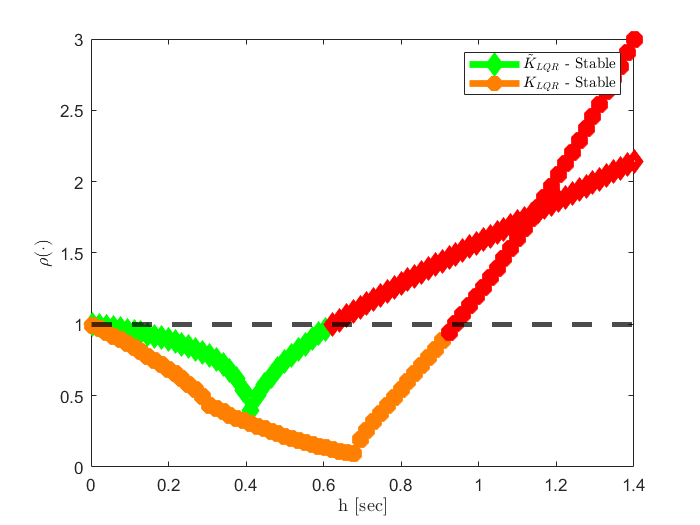

q3Dfoh.h=0.4;
[q3Dfoh.F,q3Dfoh.G] = cttodt_smartac(ct.A,ct.B,q3Dfoh.h);
[P,q3Dfoh.K,~]=idare(q3Dfoh.F,q3Dfoh.G,eye(ct.nu));
exp6.hmin=0.005;exp6.hmax=1.4;
exp6.hrange=linspace(exp6.hmin,exp6.hmax,80);%range of inter-sampling times
exp6.specrad = zeros(1, length(exp6.hrange));%vector of spectral radius vals
exp6.colors=zeros(length(exp6.hrange),3); %Initialize color matrix
exp6.dummy=0;exp6.idbound=0;
for i = 1:length(exp6.hrange)
    [F,G]=cttodt_smartac(ct.A,ct.B,exp6.hrange(i));% DT matrices
    cloopmat = F-G*q3Dfoh.K;%DT closed loop matrix
    exp6.specrad(i) = max(abs(eig(cloopmat)));
    if exp6.specrad(i) < 1
        exp6.colors(i, :) = [0 1 0]; % Green color
    else
        exp6.colors(i, :) = [1 0 0]; % Red color
        if exp6.dummy==0
            exp6.dummy=1;
            exp6.idbound=i-1;
        end
    end
end

figure
exp6.p=plot(exp6.hrange(1:exp6.idbound),exp6.specrad(1:exp6.idbound));
exp6.p.LineStyle='-';exp6.p.Marker='diamond';
exp6.p.Color=[0 1 0];exp6.p.LineWidth=4;
hold on
exp6.p2=plot(exp6.hrange(exp6.idbound:end),exp6.specrad(exp6.idbound:end));
exp6.p2.LineStyle='-';exp6.p2.Marker='diamond';
exp6.p2.Color=[1 0 0];exp6.p2.LineWidth=4;

exp5.p=plot(exp5.hrange(1:exp5.idbound),exp5.specrad(1:exp5.idbound));
exp5.p.LineStyle='-';exp5.p.Marker='*';exp5.p.MarkerSize=10;
exp5.p.Color=[1 0.5 0];exp5.p.LineWidth=4;
exp5.p2=plot(exp5.hrange(exp5.idbound:end),exp5.specrad(exp5.idbound:end));
exp5.p2.LineStyle='-';exp5.p2.Marker='*';exp5.p2.MarkerSize=10;
exp5.p2.Color=[1 0 0];exp5.p2.LineWidth=4;
yline(1,'LineWidth',3,'Color','k','LineStyle','--');
xlabel({'h [sec]'},'Interpreter','latex');
ylabel({'$\rho(\cdot)$'},'Interpreter','latex');
legend({'$\tilde{K}_{LQR}$ - Stable','','$K_{LQR}$ - Stable',''},'Interpreter','latex')

**Question 4.3: (h1 h2) or (h1 h2 h2) infinite switching**

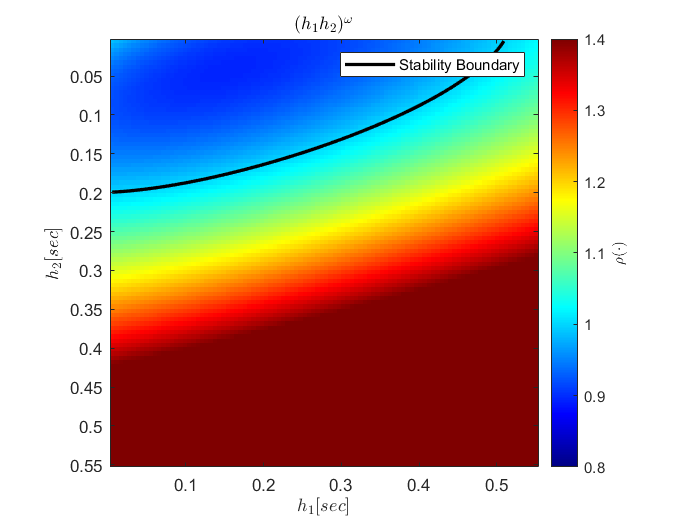

exp7.h1min = 0.005;exp7.h1max = 0.55;
numPoints = 100;exp7.h1range = linspace(exp7.h1min, exp7.h1max, numPoints);
specRadii = zeros(numPoints, numPoints);

parfor i = 1:numPoints
    h1 = exp7.h1range(i);
    [F, G] = cttodtZOHext(ct.A, ct.B, h1);  % ZOH system
    FK = F - G * [ct.K 0 0];  % Closed loop for ZOH
    for j = 1:numPoints
        h2 = exp7.h1range(j);
        [F_td, G_td] = cttodt_smartac(ct.A, ct.B, h2);  % FOH system
        FK_td = F_td - G_td * [ct.K 0 0];  % Closed loop for FOH
        cloopmat = FK*FK_td*FK_td;
        specRadii(j, i) = max(abs(eig(cloopmat))); 
    end
end

% Plot spectral radius
figure;
imagesc(exp7.h1range, exp7.h1range, specRadii, [0.8, 1.4]); 
cb=colorbar;
ylabel(cb,{'$\rho(\cdot)$'},'Interpreter','latex')
colormap jet;
hold on;
% Add a contour line 
contour(exp7.h1range, exp7.h1range, specRadii, [1, 1], 'k', 'LineWidth', 2);
legend('Stability Boundary')
xlabel({'$h_1 [sec]$'},'Interpreter','latex');
ylabel({'$h_2 [sec]$'},'Interpreter','latex');
title({'$(h_1 h_2)^\omega$'},'Interpreter','latex');
axis square;
hold off;

**Question 5**

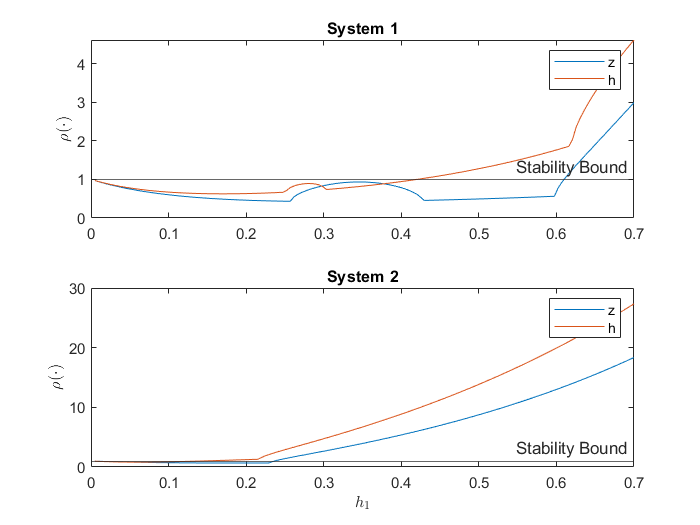

% Define System 1 and System 2
sys1.A = ct.A;
sys2.A = (1/3) * sys1.A;
sys1.B = ct.B;
sys2.B = sys1.B;

% Design gain for System 2 (same gains as Kbar)
sys2.K = place(sys2.A, sys2.B, ct.clpoles);

% Experiment parameters
exp8.h1min = 0.005;
exp8.h1max = 0.7;
numPoints = 150;
exp8.h1range = linspace(exp8.h1min, exp8.h1max, numPoints);
specRad1 = zeros(numPoints, length(strategies)^2);
specRad2 = zeros(numPoints, length(strategies)^2);
strategies = {'z', 'h'};

it = 1;
for s1 = 1:length(strategies)
    for s2 = 1:length(strategies)
        strategy1 = strategies{s1};
        strategy2 = strategies{s2};
        for i = 1:numPoints
            h1 = exp8.h1range(i);
            [F1_s1, F0_s1] = cttodtq5(sys1.A, sys1.B, h1, strategy1, ct.K); % System1
            cloopmat1 = (F0_s1)^2 * F1_s1 * (F0_s1)^3;
            specrad1 = max(abs(eig(cloopmat1)));
            h2 = 3*h1;
            [F1_s2, F0_s2] = cttodtq5(sys2.A, sys2.B, h2, strategy2, sys2.K); % System2
            cloopmat2 = F0_s2 * F1_s2;
            specrad2 = max(abs(eig(cloopmat2)));
            specRad1(i, it) = specrad1;
            specRad2(i, it) = specrad2;
        end
        it = it + 1;
    end
end

% Plotting
figure;

% Subplot for specrad1
subplot(2, 1, 1);
for j = 1:2:size(specRad1, 2)
    plot(exp8.h1range, specRad1(:, j));
    hold on;
end
ylabel({'$\rho(\cdot)$'},'interpreter','latex');
yline(1,'Label','Stability Bound')
legend('z','h')
title('System 1');

% Subplot for specrad2
subplot(2, 1, 2);
for j = 1:2
    plot(exp8.h1range, specRad2(:, j));
    hold on;
end

xlabel({'$h_1$'},'interpreter','latex');
ylabel({'$\rho(\cdot)$'},'interpreter','latex');
title('System 2');
yline(1,'Label','Stability Bound')
legend('z','h')
hold off;